将指定图像文件中指定的颜色视为背景，去除之

本函数将指定路径中的图片文件，去除周围指定颜色的背景；内部的背景像素全部设为完全透明，然后保存到指定的PNG文件

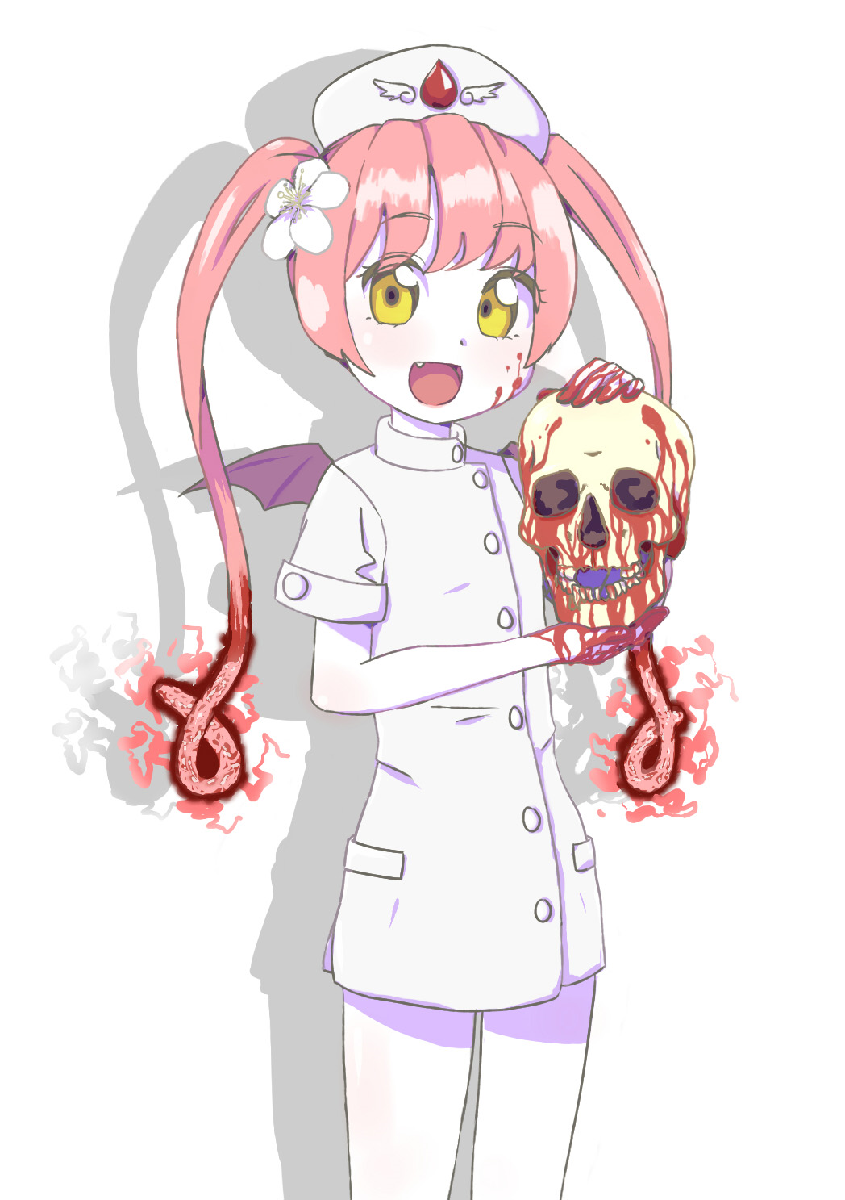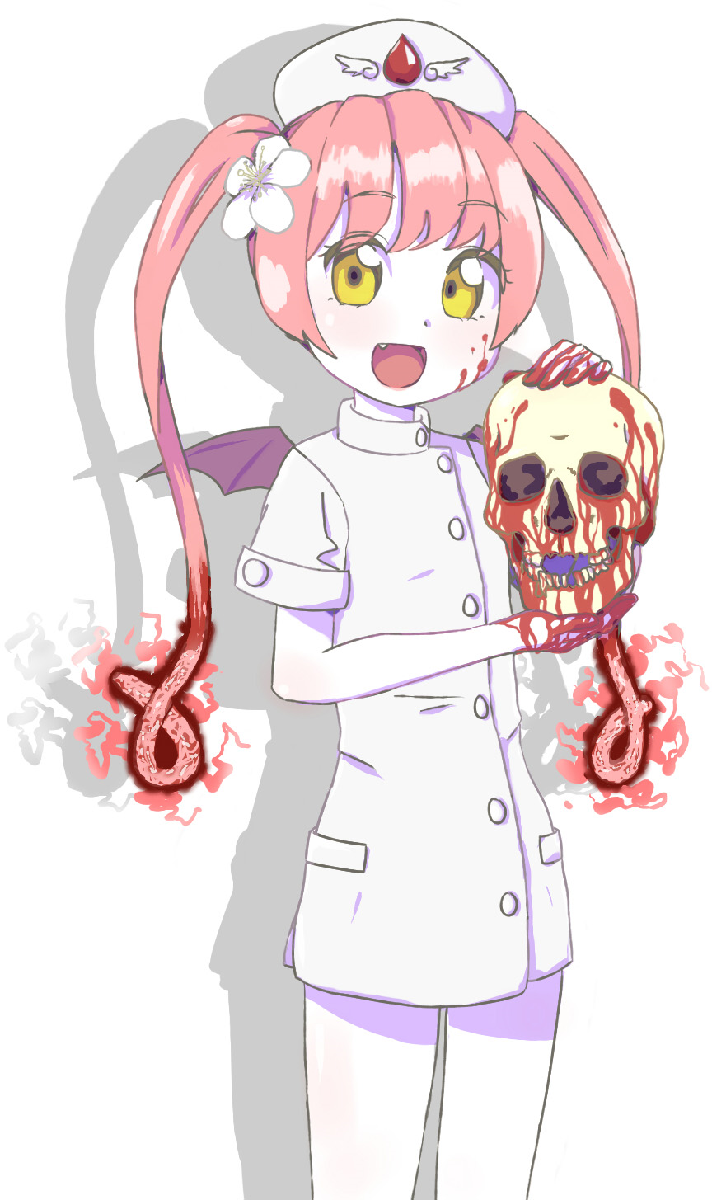

两张图看似一致，实际上右图四周的白边都被裁掉了，而且所有白色像素也变成了全透明，放在黑色背景下就能看出来了。

## 名称值参数

InputPath(1,1)string，输入图像路径，默认打开文件选择对话框供用户手动选择。仅支持PNG或JPG图像。

BackgroundColor(1,1,3)uint8，背景色。JPG图像，默认将白色作为背景裁去；PNG图像，默认仅裁去全透明边框。

OutputPath(1,1)string，输出图像路径，默认打开保存选择对话框供用户手动选择。仅支持PNG图像。

function StripBackground(options)
arguments
	options.InputPath(1,1)string=EbolaChan.WindowsTools.OpenFileDialog("Title","选择图像文件","Filter","24位彩图|*.png;*.jpg")
	options.BackgroundColor uint8=[]
	options.OutputPath(1,1)string=EbolaChan.WindowsTools.SaveFileDialog("Title","选择保存位置","Filter","PNG图像|*.png")
end
InputPath=options.InputPath;
BackgroundColor=options.BackgroundColor;
[~,~,Extension]=fileparts(InputPath);
IsPNG=Extension==".png";
if IsPNG
	[Image,~,Alpha]=imread(InputPath);
	if isempty(BackgroundColor)
		NotBackground=Alpha>0;
	else
		NotBackground=any(Image~=BackgroundColor,3)&Alpha>0;
	end
	Alpha(~NotBackground)=0;
else
	Image=imread(InputPath);
	if isempty(BackgroundColor)
		BackgroundColor=cat(3,255,255,255);
	end
	NotBackground=any(Image~=BackgroundColor,3);
end
VerticalNB=any(NotBackground,2);
HorizontalNB=any(NotBackground,1);
NBIndex={find(VerticalNB,1):find(VerticalNB,1,"last"),find(HorizontalNB,1):find(HorizontalNB,1,"last"),':'};
if IsPNG
	imwrite(Image(NBIndex{:}),options.OutputPath,"Alpha",double(Alpha(NBIndex{:}))/255);
else
	imwrite(Image(NBIndex{:}),options.OutputPath,"Alpha",double(NotBackground(NBIndex{:})));
end